# Homework 14: 

# Amelia Rotondo, CWID: 887925113

warning off; 

## Section 11.1:

#### Problem 1: 

Equation 11.1.12: $P(t)=\frac{M}{1+e^{-rM(t-t^*)}}$

Logistic Population Growth: $\frac{dP}{dt}=r(M-P)P$

Initial Equation: $t^*=t_0 - (\frac{1}{rM})*ln[\frac{P_0 }{(M-P_0)}]$

Derived Equation: $ln[\frac{P}{(M-P)}]=rMt-rMt^*$

#### Problem 3:

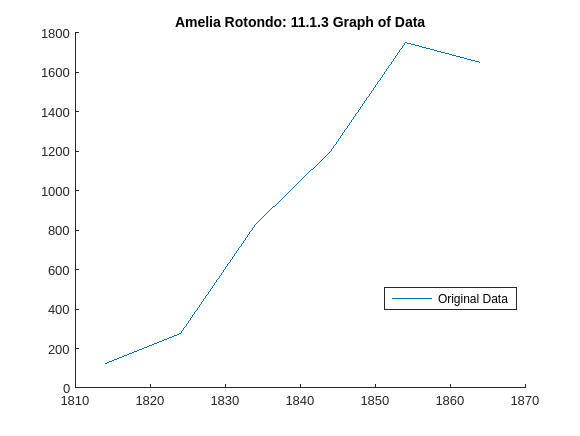

% Initial Data 
t  = 1814:10:1864; 
P  = [125, 275, 830, 1200, 1750, 1650];

% Plot the Data 
figure(1); clf; hold on; 
title('Amelia Rotondo: 11.1.3 Graph of Data');
legend('Location', 'best');
plot(t, P, 'DisplayName', 'Original Data');

Based on this Plot, I believe that M is about 1800

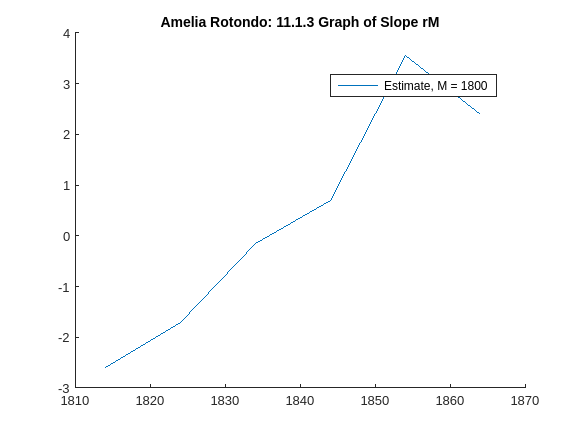

% Add the Estimate of M 
M = 1800; 
P_est = log(P./(M-P));

% Plot the Estimate
figure(2); clf; hold on; 
title('Amelia Rotondo: 11.1.3 Graph of Slope rM');
legend('Location', 'best');
plot(t, P_est, 'DisplayName', 'Estimate, M = 1800');

Based on this plot, a logistic curve seems unreasonable, since there is not a straight line. Therefore, I won't be estimating $rM
$and $t^*$.

#### Problem 4: 

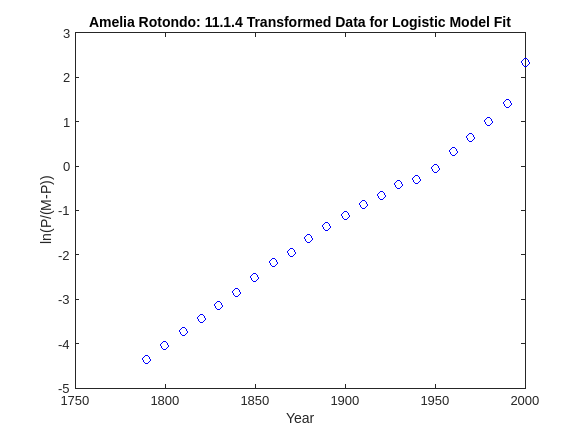

% Original Data
Year = [1790, 1800, 1810, 1820, 1830, 1840, 1850, 1860, 1870, 1880, 1890, 1900, 1910, 1920, 1930, 1940, 1950, 1960, 1970, 1980, 1990, 2000, 2010];
Observed_Population = [3929000, 5308000, 7240000, 9638000, 12866000, 17069000, 23192000, 31443000, 38558000, 50156000, 62948000, 75995000, 91972000, 105711000, 122755000, 131669000, 150697000, 179323000, 203212000, 226505000, 248710000, 281416000, 308746000];
Predicted_Population = [3929000, 5336000, 7227000, 9756000, 13108000, 17505000, 23191000, 30410000, 39370000, 50175000, 62767000, 76867000, 91970000, 107393000, 122396000, 136317000, 148677000, 159230000, 167943000, 174941000, 180440000, 184677000, 187905000];
Percent_Error = [0.0, 0.5, 0.2, 1.2, 1.9, 2.6, 0.0, 3.3, 2.1, 0.0, 0.3, 1.1, 0.0, 1.6, 0.3, 3.5, 1.3, 11.2, 17.4, 22.8, 27.5, 34.4, 39.1];
t = Year; 
P = Observed_Population; 

% Estimate of M
M = max(P); 

% Transformation
Transformed_Data = log(P ./ (M - P));

% Linear Fit
coeffs = polyfit(t, Transformed_Data, 1);
rM_est = coeffs(1); 
t_prime_est = -coeffs(2) / rM_est; 

% Plotting for visualization (optional)
figure;
plot(t, Transformed_Data, 'bo');
xlabel('Year');
ylabel('ln(P/(M-P))');
title('Amelia Rotondo: 11.1.4 Transformed Data for Logistic Model Fit');

fprintf('r*M: %.9f * %.9f\n t*: %.9f', rM_est(1), t_prime_est);

r*M: NaN * NaN
 t*: 

## Section 11.2:

#### Problem 3: 

#### Problem 4: 

#### Problem 5:

## Section 11.4:

#### Problem 1a:

#### Problem 1d:

#### Problem 2: 

#### Problem 5: 

#### Problem 6: 

#### Problem 8: